clear; close all
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% output 1 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
syms M m l g u y y_dot theta theta_dot t q1 q2

% define the system state
x = [y; y_dot; theta; theta_dot];

% define system dynamics
y_ddot=(-m*l*sin(theta)*theta_dot^2 + m*g*sin(theta)*cos(theta) + u)/...
    (M + m*sin(theta)^2);
theta_ddot=(-m*l*sin(theta)*cos(theta)*theta_dot^2 + (M+m)*g*sin(theta) +...
    u*cos(theta))/...
    (l*(M+m*sin(theta)^2));

xdot = [y_dot; y_ddot; theta_dot;theta_ddot]

$$xdot = \left(\begin{array}{c} \dot{y}\\ \frac{-l\,m\,\sin\left(\theta \right)\,{\dot{\theta }}^{2}+u+g\,m\,\cos\left(\theta \right)\,\sin\left(\theta \right)}{m\,{\sin\left(\theta \right)}^{2}+M}\\ \dot{\theta }\\ \frac{-l\,m\,\cos\left(\theta \right)\,\sin\left(\theta \right)\,{\dot{\theta }}^{2}+u\,\cos\left(\theta \right)+g\,\sin\left(\theta \right)\,\left(M+m\right)}{l\,\left(m\,{\sin\left(\theta \right)}^{2}+M\right)} \end{array}\right)$$



% define the set of parameters specific to our ODE
parameters.M = 1.0731;
parameters.m = 0.2300;
parameters.l= 0.3302;
parameters.g = 9.8;

%linearization starts here

% equilibrium point
x_bar = [0; 0; 0; 0];
u_bar = 0;

% find jacobian for any point x
A_raw = jacobian(xdot,x);
B_raw = jacobian(xdot,u);

% substitute parameters as defined above
A_specific = subs(subs(subs(subs(A_raw,m,parameters.m),M,parameters.M), l, parameters.l), g, parameters.g);
B_specific = subs(subs(subs(subs(B_raw,m,parameters.m),M,parameters.M), l, parameters.l), g, parameters.g);

% find jacobian for equilibrium point
A = subs(subs(A_specific,x,x_bar), u, u_bar)

$$A = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & 0 & \frac{460}{219} & 0\\ 0 & 0 & 0 & 1\\ 0 & 0 & \frac{13031000}{361569} & 0 \end{array}\right)$$

B = subs(subs(B_specific,x,x_bar), u, u_bar)

$$B = \left(\begin{array}{c} 0\\ \frac{10000}{10731}\\ 0\\ \frac{50000000}{17716881} \end{array}\right)$$




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% output 2 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
A_double = double(A);
B_double = double(B);
poles_1 = [-1, -2, -3, -4];
poles_2 = [-1, -2, -3, -20];
negK_1 = place(A_double, B_double,poles_1);
negK_2 = place(A_double, B_double,poles_2);
K_1 = -negK_1               % to convert to the convention used in class

K_1 =     0.8678    1.8078  -25.4587   -4.1403


K_2 = -negK_2               % to convert to the convention used in class

K_2 =     4.3388    8.1715  -60.6213  -11.9110



%sanity check of closed loop poles_1 -> all poles_1 are at desired locations: [-1, -2, -3, -4]
A_cl_1 = A+B*K_1;           % close-loop system
double(eig(A_cl_1))

ans =   -4.0000 - 0.0000i
  -3.0000 - 0.0000i
  -2.0000 + 0.0000i
  -1.0000 + 0.0000i



%sanity check of closed loop poles_2 -> all poles_2 are at desired locations: [-1, -2, -3, -20]
A_cl_2 = A+B*K_2;           % close-loop system
double(eig(A_cl_2))

ans =  -20.0000 - 0.0000i
  -3.0000 - 0.0000i
  -2.0000 - 0.0000i
  -1.0000 + 0.0000i


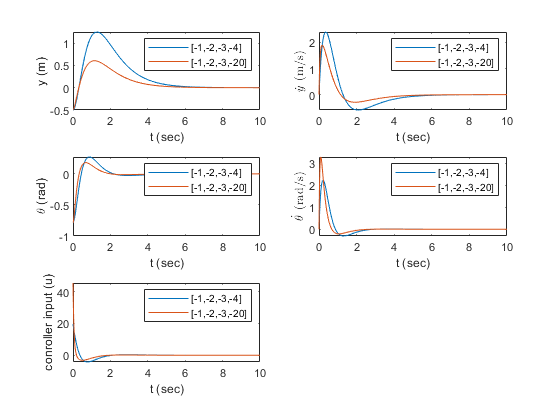


% create the linearized close-loop system
Xdot_linearized_controlled_1 = A_cl_1 * x;
inverted_pen_1 = matlabFunction(Xdot_linearized_controlled_1,'Vars',{t, x});

Xdot_linearized_controlled_2 = A_cl_2 * x;
inverted_pen_2 = matlabFunction(Xdot_linearized_controlled_2,'Vars',{t, x});


options = odeset('RelTol',1e-7,'AbsTol',1e-7);  
Tspan = linspace(0,10,1e3);

x0 = [-0.5; 0; -pi/4; 0];
[t_val_1,x_val_1]=ode45(inverted_pen_1,Tspan,x0,options);
[t_val_2,x_val_2]=ode45(inverted_pen_2,Tspan,x0,options);


%plotting figures
subplot(3,2,1)              %plotting y
plot(t_val_1, x_val_1(:,1))
hold on                     
plot(t_val_2, x_val_2(:,1))
legend('[-1,-2,-3,-4]', '[-1,-2,-3,-20]')
xlabel("t (sec)")
ylabel("y (m)")
subplot(3,2,2)              %plotting y_dot
plot(t_val_1, x_val_1(:,2))
hold on
plot(t_val_2, x_val_2(:,2))
legend('[-1,-2,-3,-4]', '[-1,-2,-3,-20]')
xlabel("t (sec)")
ylabel("$\dot{y}$ (m/s)", 'Interpreter','latex')
subplot(3,2,3)              %plotting theta
plot(t_val_1, x_val_1(:,3))
hold on
plot(t_val_2, x_val_2(:,3))
legend('[-1,-2,-3,-4]', '[-1,-2,-3,-20]')
xlabel("t (sec)")
ylabel("\theta (rad)")
subplot(3,2,4)              %plotting theta_dot
plot(t_val_1, x_val_1(:,4))
hold on
plot(t_val_2, x_val_2(:,4))
legend('[-1,-2,-3,-4]', '[-1,-2,-3,-20]')
xlabel("t (sec)")
ylabel("$\dot{\theta}$ (rad/s)", 'Interpreter','latex')
subplot(3,2,5)              %plotting control input u
u_1 = -negK_1*x_val_1';                 % input u = K_1x; convert rows of x_val_1 to become columns of x's
u_2 = -negK_2*x_val_2';                 % input u = K_1x; convert rows of x_val_1 to become columns of x's
u_n_by_1_1 = u_1';                       % convert u to Nx1 as requested in lab manual
u_n_by_1_2 = u_2';                       % convert u to Nx1 as requested in lab manual

plot(t_val_1, u_n_by_1_1)   
hold on
plot(t_val_1, u_n_by_1_2)
legend('[-1,-2,-3,-4]', '[-1,-2,-3,-20]')
xlabel("t (sec)")
ylabel("conroller input (u)")


% response:more negative poles -> more drastic response -> less transient
% time; all states are affected; 
%

Qc = ctrb(A_double,B_double);       %obtain the controllability matrix of the system
P_basis = orth(Qc)

P_basis =    -0.0584    0.0000   -0.9983   -0.0000
   -0.0000    0.0584   -0.0000    0.9983
   -0.9983         0    0.0584         0
   -0.0000    0.9983   -0.0000   -0.0584


% because each basis of P has non-zero coordinate in both the cartposition
% subsystem, and pendulum subsystem, it is IMPOSSIBLE to decouple the 2
% subsystems -> cannot speed up the cart position convergence ALONE.


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% output 3 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Q_base = [q1, 0, 0, 0;
    0, 0, 0, 0;
    0, 0, q2, 0'
    0, 0, 0, 0];
sys = ss(A_double, B_double, [], []);

%%%%%%%%%%%%%%%%%%%%%varying q1
q1_val_1 = 0.1;
q1_val_2 = 0.005;
q2_val = 5;
R = [0.5];

%obtain the Q matrix for each configuration of q1
Q_q1_1 = double(subs(subs(Q_base, q2, q2_val), q1, q1_val_1));
Q_q1_2 = double(subs(subs(Q_base, q2, q2_val), q1, q1_val_2));

negK_1 = lqr(sys, Q_q1_1,R);
negK_2 = lqr(sys, Q_q1_2,R);
K_1 = -negK_1               % to convert to the convention used in class

K_1 =     0.4472    1.2429  -29.6951   -4.9864


K_2 = -negK_2               % to convert to the convention used in class

K_2 =     0.1000    0.5509  -27.6408   -4.6051


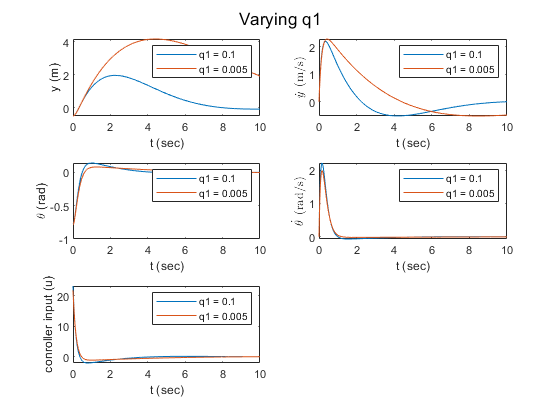


A_cl_1 = A+B*K_1;           % close-loop system 1
A_cl_2 = A+B*K_2;           % close-loop system 2


% create the linearized close-loop system
Xdot_linearized_controlled_1 = A_cl_1 * x;
inverted_pen_1 = matlabFunction(Xdot_linearized_controlled_1,'Vars',{t, x});

Xdot_linearized_controlled_2 = A_cl_2 * x;
inverted_pen_2 = matlabFunction(Xdot_linearized_controlled_2,'Vars',{t, x});


options = odeset('RelTol',1e-7,'AbsTol',1e-7);  
Tspan = linspace(0,10,1e3);

x0 = [-0.5; 0; -pi/4; 0];
[t_val_1,x_val_1]=ode45(inverted_pen_1,Tspan,x0,options);
[t_val_2,x_val_2]=ode45(inverted_pen_2,Tspan,x0,options);


%plotting figures
figure
subplot(3,2,1)              %plotting y
plot(t_val_1, x_val_1(:,1))
hold on                     
plot(t_val_2, x_val_2(:,1))
legend('q1 = 0.1', 'q1 = 0.005')
xlabel("t (sec)")
ylabel("y (m)")
subplot(3,2,2)              %plotting y_dot
plot(t_val_1, x_val_1(:,2))
hold on
plot(t_val_2, x_val_2(:,2))
legend('q1 = 0.1', 'q1 = 0.005')
xlabel("t (sec)")
ylabel("$\dot{y}$ (m/s)", 'Interpreter','latex')
subplot(3,2,3)              %plotting theta
plot(t_val_1, x_val_1(:,3))
hold on
plot(t_val_2, x_val_2(:,3))
legend('q1 = 0.1', 'q1 = 0.005')
xlabel("t (sec)")
ylabel("\theta (rad)")
subplot(3,2,4)              %plotting theta_dot
plot(t_val_1, x_val_1(:,4))
hold on
plot(t_val_2, x_val_2(:,4))
legend('q1 = 0.1', 'q1 = 0.005')
xlabel("t (sec)")
ylabel("$\dot{\theta}$ (rad/s)", 'Interpreter','latex')
subplot(3,2,5)              %plotting control input u
u_1 = -negK_1*x_val_1';                 % input u = K_1x; convert rows of x_val_1 to become columns of x's
u_2 = -negK_2*x_val_2';                 % input u = K_1x; convert rows of x_val_1 to become columns of x's
u_n_by_1_1 = u_1';                       % convert u to Nx1 as requested in lab manual
u_n_by_1_2 = u_2';                       % convert u to Nx1 as requested in lab manual

plot(t_val_1, u_n_by_1_1)   
hold on
plot(t_val_1, u_n_by_1_2)
legend('q1 = 0.1', 'q1 = 0.005')
xlabel("t (sec)")
ylabel("conroller input (u)")
sgtitle('Varying q1') 



%%%%%%%%%%%%%%%%%%%%%varying q2
q1_val = 0.05;
q2_val_1 = 1;
q2_val_2 = 2000;

R = [0.5];

%obtain the Q matrix for each configuration of q1
Q_q2_1 = double(subs(subs(Q_base, q2, q2_val_1), q1, q1_val));
Q_q2_2 = double(subs(subs(Q_base, q2, q2_val_2), q1, q1_val));

negK_1 = lqr(sys, Q_q2_1,R);
negK_2 = lqr(sys, Q_q2_2,R);
K_1 = -negK_1               % to convert to the convention used in class

K_1 =     0.3162    1.0162  -28.7703   -4.8427


K_2 = -negK_2               % to convert to the convention used in class

K_2 =     0.3162    2.0785  -79.7095   -8.1972


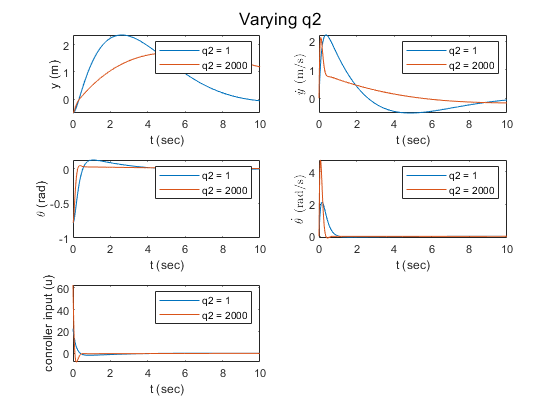


A_cl_1 = A+B*K_1;           % close-loop system 1
A_cl_2 = A+B*K_2;           % close-loop system 2

% create the linearized close-loop system
Xdot_linearized_controlled_1 = A_cl_1 * x;
inverted_pen_1 = matlabFunction(Xdot_linearized_controlled_1,'Vars',{t, x});

Xdot_linearized_controlled_2 = A_cl_2 * x;
inverted_pen_2 = matlabFunction(Xdot_linearized_controlled_2,'Vars',{t, x});


options = odeset('RelTol',1e-7,'AbsTol',1e-7);  
Tspan = linspace(0,10,1e3);

x0 = [-0.5; 0; -pi/4; 0];
[t_val_1,x_val_1]=ode45(inverted_pen_1,Tspan,x0,options);
[t_val_2,x_val_2]=ode45(inverted_pen_2,Tspan,x0,options);


%plotting figures
figure
subplot(3,2,1)              %plotting y
plot(t_val_1, x_val_1(:,1))
hold on                     
plot(t_val_2, x_val_2(:,1))
legend('q2 = 1', 'q2 = 2000')
xlabel("t (sec)")
ylabel("y (m)")
subplot(3,2,2)              %plotting y_dot
plot(t_val_1, x_val_1(:,2))
hold on
plot(t_val_2, x_val_2(:,2))
legend('q2 = 1', 'q2 = 2000')
xlabel("t (sec)")
ylabel("$\dot{y}$ (m/s)", 'Interpreter','latex')
subplot(3,2,3)              %plotting theta
plot(t_val_1, x_val_1(:,3))
hold on
plot(t_val_2, x_val_2(:,3))
legend('q2 = 1', 'q2 = 2000')
xlabel("t (sec)")
ylabel("\theta (rad)")
subplot(3,2,4)              %plotting theta_dot
plot(t_val_1, x_val_1(:,4))
hold on
plot(t_val_2, x_val_2(:,4))
legend('q2 = 1', 'q2 = 2000')
xlabel("t (sec)")
ylabel("$\dot{\theta}$ (rad/s)", 'Interpreter','latex')
subplot(3,2,5)              %plotting control input u
u_1 = -negK_1*x_val_1';                 % input u = K_1x; convert rows of x_val_1 to become columns of x's
u_2 = -negK_2*x_val_2';                 % input u = K_1x; convert rows of x_val_1 to become columns of x's
u_n_by_1_1 = u_1';                       % convert u to Nx1 as requested in lab manual
u_n_by_1_2 = u_2';                       % convert u to Nx1 as requested in lab manual

plot(t_val_1, u_n_by_1_1)   
hold on
plot(t_val_1, u_n_by_1_2)
legend('q2 = 1', 'q2 = 2000')
xlabel("t (sec)")
ylabel("conroller input (u)")
sgtitle('Varying q2') 


%%%%%%%%%%%%%%%%%%%%%varying R
q1_val = 0.05;
q2_val = 5;

R_1 = [0.005];
R_2 = [10];

%obtain the Q matrix for each configuration of q1
Q = double(subs(subs(Q_base, q2, q2_val), q1, q1_val));

negK_1 = lqr(sys, Q, R_1);
negK_2 = lqr(sys, Q, R_2);
K_1 = -negK_1               % to convert to the convention used in class

K_1 =     3.1623    5.2894  -56.1219   -7.9941


K_2 = -negK_2               % to convert to the convention used in class

K_2 =     0.0707    0.4532  -27.0041   -4.5224


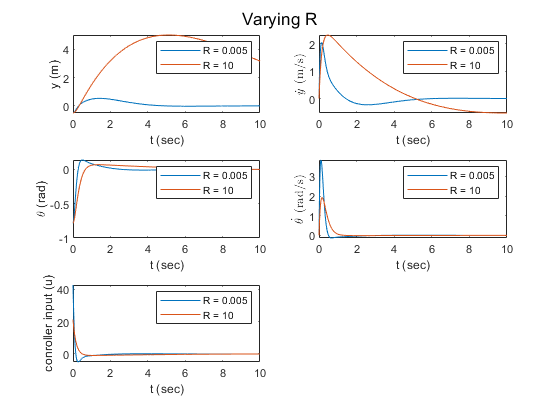


A_cl_1 = A+B*K_1;           % close-loop system 1
A_cl_2 = A+B*K_2;           % close-loop system 2

% create the linearized close-loop system
Xdot_linearized_controlled_1 = A_cl_1 * x;
inverted_pen_1 = matlabFunction(Xdot_linearized_controlled_1,'Vars',{t, x});

Xdot_linearized_controlled_2 = A_cl_2 * x;
inverted_pen_2 = matlabFunction(Xdot_linearized_controlled_2,'Vars',{t, x});


options = odeset('RelTol',1e-7,'AbsTol',1e-7);  
Tspan = linspace(0,10,1e3);

x0 = [-0.5; 0; -pi/4; 0];
[t_val_1,x_val_1]=ode45(inverted_pen_1,Tspan,x0,options);
[t_val_2,x_val_2]=ode45(inverted_pen_2,Tspan,x0,options);


%plotting figures
figure
subplot(3,2,1)              %plotting y
plot(t_val_1, x_val_1(:,1))
hold on                     
plot(t_val_2, x_val_2(:,1))
legend('R = 0.005', 'R = 10')
xlabel("t (sec)")
ylabel("y (m)")
subplot(3,2,2)              %plotting y_dot
plot(t_val_1, x_val_1(:,2))
hold on
plot(t_val_2, x_val_2(:,2))
legend('R = 0.005', 'R = 10')
xlabel("t (sec)")
ylabel("$\dot{y}$ (m/s)", 'Interpreter','latex')
subplot(3,2,3)              %plotting theta
plot(t_val_1, x_val_1(:,3))
hold on
plot(t_val_2, x_val_2(:,3))
legend('R = 0.005', 'R = 10')
xlabel("t (sec)")
ylabel("\theta (rad)")
subplot(3,2,4)              %plotting theta_dot
plot(t_val_1, x_val_1(:,4))
hold on
plot(t_val_2, x_val_2(:,4))
legend('R = 0.005', 'R = 10')
xlabel("t (sec)")
ylabel("$\dot{\theta}$ (rad/s)", 'Interpreter','latex')
subplot(3,2,5)              %plotting control input u
u_1 = -negK_1*x_val_1';                 % input u = K_1x; convert rows of x_val_1 to become columns of x's
u_2 = -negK_2*x_val_2';                 % input u = K_1x; convert rows of x_val_1 to become columns of x's
u_n_by_1_1 = u_1';                       % convert u to Nx1 as requested in lab manual
u_n_by_1_2 = u_2';                       % convert u to Nx1 as requested in lab manual

plot(t_val_1, u_n_by_1_1)   
hold on
plot(t_val_1, u_n_by_1_2)
legend('R = 0.005', 'R = 10')
xlabel("t (sec)")
ylabel("conroller input (u)")
sgtitle('Varying R') 





% Respone: 
% larger q2 causes the response in theta to be more rapid (larger changes
% in shorter time), while decreasing the settling time in y. larger q1
% causes the response in y to be more rapid (larger changes in shorter 
% time), while decreasing the settling time/performancein theta. 

% (my guess, not too sure) increasing R increases the settling time of both
% outputs (theta, y). An interesting note: the transient time of y is
% significantly more than the transient time of theta because q1 is 100
% times less than q2.





 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% output 4%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
q1_val = 0.05;
q2_val = 5;
R = [0.005];

%obtain the Q matrix for each configuration of q1
Q = double(subs(subs(Q_base, q2, q2_val), q1, q1_val));

negK = lqr(sys, Q, R);
K = -negK               % to convert to the convention used in class

K =     3.1623    5.2894  -56.1219   -7.9941


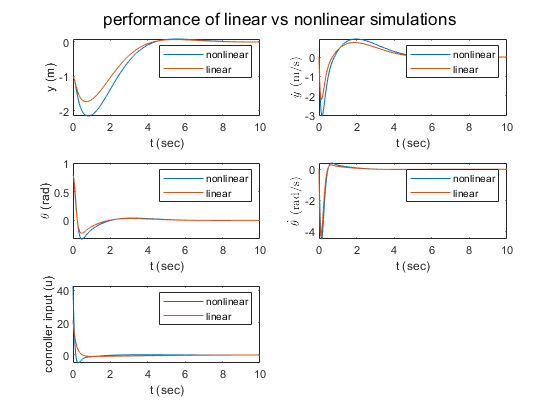


% nonlinear system x_dot = f(x,u), with parameters substituted
xdot_specific = subs(subs(subs(subs(xdot,m,parameters.m),M,parameters.M), l, parameters.l), g, parameters.g);
xdot_specific_controlled = subs(xdot_specific,u,K*x);
inverted_pen_nonlinear = matlabFunction(xdot_specific_controlled,'Vars',{t, x});

% linearized system
Xdot_linearized_controlled = (A+B*K) * x;
inverted_pen_linear = matlabFunction(Xdot_linearized_controlled,'Vars',{t, x});


%simulate both systems
options = odeset('RelTol',1e-7,'AbsTol',1e-7);  
Tspan = linspace(0,10,1e3);

x0 = [-1; 0; pi/4; 0];
[t_val_nl, x_val_nl]=ode45(inverted_pen_nonlinear,Tspan,x0,options);
[t_val_l, x_val_l]=ode45(inverted_pen_linear,Tspan,x0,options);


%plotting figures
figure
subplot(3,2,1)              %plotting y
plot(t_val_nl, x_val_nl(:,1))
hold on                     
plot(t_val_l, x_val_l(:,1))
legend('nonlinear', 'linear')
xlabel("t (sec)")
ylabel("y (m)")
subplot(3,2,2)              %plotting y_dot
plot(t_val_nl, x_val_nl(:,2))
hold on                     
plot(t_val_l, x_val_l(:,2))
legend('nonlinear', 'linear')
xlabel("t (sec)")
ylabel("$\dot{y}$ (m/s)", 'Interpreter','latex')
subplot(3,2,3)              %plotting theta
plot(t_val_nl, x_val_nl(:,3))
hold on                     
plot(t_val_l, x_val_l(:,3))
legend('nonlinear', 'linear')
xlabel("t (sec)")
ylabel("\theta (rad)")
subplot(3,2,4)              %plotting theta_dot
plot(t_val_nl, x_val_nl(:,4))
hold on                     
plot(t_val_l, x_val_l(:,4))
legend('nonlinear', 'linear')
xlabel("t (sec)")
ylabel("$\dot{\theta}$ (rad/s)", 'Interpreter','latex')
subplot(3,2,5)              %plotting control input u
u_1 = -negK_1*x_val_1';                 % input u = K_1x; convert rows of x_val_1 to become columns of x's
u_2 = -negK_2*x_val_2';                 % input u = K_1x; convert rows of x_val_1 to become columns of x's
u_n_by_1_1 = u_1';                       % convert u to Nx1 as requested in lab manual
u_n_by_1_2 = u_2';                       % convert u to Nx1 as requested in lab manual

plot(t_val_1, u_n_by_1_1)   
hold on
plot(t_val_1, u_n_by_1_2)
legend('nonlinear', 'linear')
xlabel("t (sec)")
ylabel("conroller input (u)")
sgtitle('performance of linear vs nonlinear simulations')

 %%%%%%%%%%%%%%%%%%Varying initial y value
y0_val = -12;            % initial y position
q1_val = 0.05;
q2_val = 5;
R = [0.005];

%obtain the Q matrix for each configuration of q1
Q = double(subs(subs(Q_base, q2, q2_val), q1, q1_val));

negK = lqr(sys, Q, R);
K = -negK               % to convert to the convention used in class

K =     3.1623    5.2894  -56.1219   -7.9941


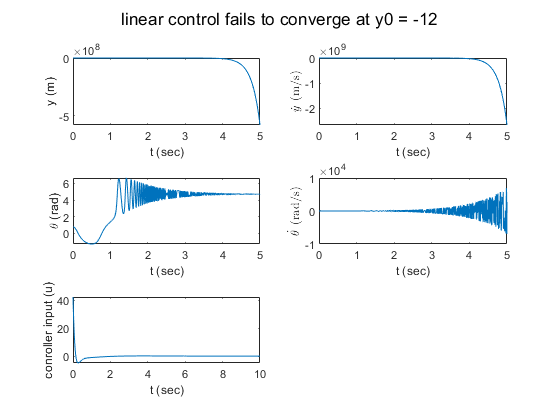


% nonlinear system x_dot = f(x,u), with parameters substituted
xdot_specific = subs(subs(subs(subs(xdot,m,parameters.m),M,parameters.M), l, parameters.l), g, parameters.g);
xdot_specific_controlled = subs(xdot_specific,u,K*x);
inverted_pen_nonlinear = matlabFunction(xdot_specific_controlled,'Vars',{t, x});


%simulate the nonlinear system systems
options = odeset('RelTol',1e-7,'AbsTol',1e-7);  
Tspan = linspace(0,5,1e3);

x0 = [y0_val; 0; pi/4; 0];
[t_val_nl, x_val_nl]=ode45(inverted_pen_nonlinear,Tspan,x0,options);


%plotting figures
figure
subplot(3,2,1)              %plotting y
plot(t_val_nl, x_val_nl(:,1))
xlabel("t (sec)")
ylabel("y (m)")
subplot(3,2,2)              %plotting y_dot
plot(t_val_nl, x_val_nl(:,2))
xlabel("t (sec)")
ylabel("$\dot{y}$ (m/s)", 'Interpreter','latex')
subplot(3,2,3)              %plotting theta
plot(t_val_nl, x_val_nl(:,3))
xlabel("t (sec)")
ylabel("\theta (rad)")
subplot(3,2,4)              %plotting theta_dot
plot(t_val_nl, x_val_nl(:,4))
xlabel("t (sec)")
ylabel("$\dot{\theta}$ (rad/s)", 'Interpreter','latex')
subplot(3,2,5)              %plotting control input u
u_1 = -negK_1*x_val_1';                 % input u = K_1x; convert rows of x_val_1 to become columns of x's
u_2 = -negK_2*x_val_2';                 % input u = K_1x; convert rows of x_val_1 to become columns of x's
u_n_by_1_1 = u_1';                       % convert u to Nx1 as requested in lab manual
u_n_by_1_2 = u_2';                       % convert u to Nx1 as requested in lab manual

plot(t_val_1, u_n_by_1_1)   
xlabel("t (sec)")
ylabel("conroller input (u)")
sgtitle(sprintf('linear control fails to converge at y0 = %d', y0_val))


%discussion:
% had to reduce the time span to 0-5 because at t=5, y is already -5e8.
% Beyond this point, the system runs into numerical error and stalls

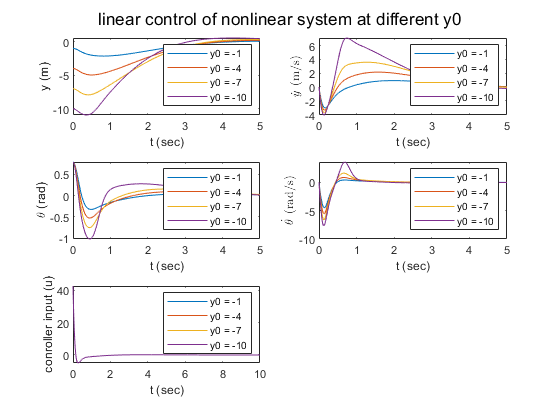

figure
for y0_val=1:3:11
    x0 = [-y0_val; 0; pi/4; 0];
    [t_val_nl, x_val_nl]=ode45(inverted_pen_nonlinear,Tspan,x0,options);
    
    
    subplot(3,2,1)              %plotting y
    plot(t_val_nl, x_val_nl(:,1),'DisplayName',sprintf("y0 = %d",-y0_val))
    legend
    hold on
    xlabel("t (sec)")
    ylabel("y (m)")
    subplot(3,2,2)              %plotting y_dot
    plot(t_val_nl, x_val_nl(:,2),'DisplayName',sprintf("y0 = %d",-y0_val))
    legend
    hold on
    xlabel("t (sec)")
    ylabel("$\dot{y}$ (m/s)", 'Interpreter','latex')
    subplot(3,2,3)              %plotting theta
    plot(t_val_nl, x_val_nl(:,3),'DisplayName',sprintf("y0 = %d",-y0_val))
    legend
    hold on
    xlabel("t (sec)")
    ylabel("\theta (rad)")
    subplot(3,2,4)              %plotting theta_dot
    plot(t_val_nl, x_val_nl(:,4),'DisplayName',sprintf("y0 = %d",-y0_val))
    legend
    hold on
    xlabel("t (sec)")
    ylabel("$\dot{\theta}$ (rad/s)", 'Interpreter','latex')
    subplot(3,2,5)              %plotting control input u
    u_1 = -negK_1*x_val_1';                 % input u = K_1x; convert rows of x_val_1 to become columns of x's
    u_2 = -negK_2*x_val_2';                 % input u = K_1x; convert rows of x_val_1 to become columns of x's
    u_n_by_1_1 = u_1';                       % convert u to Nx1 as requested in lab manual
    u_n_by_1_2 = u_2';                       % convert u to Nx1 as requested in lab manual
    
    plot(t_val_1, u_n_by_1_1,'DisplayName',sprintf("y0 = %d",-y0_val))
    legend 
    hold on
    xlabel("t (sec)")
    ylabel("conroller input (u)")
    sgtitle(sprintf('linear control of nonlinear system at different y0'))
end